# One-step methods for the ODE

## Taks 1

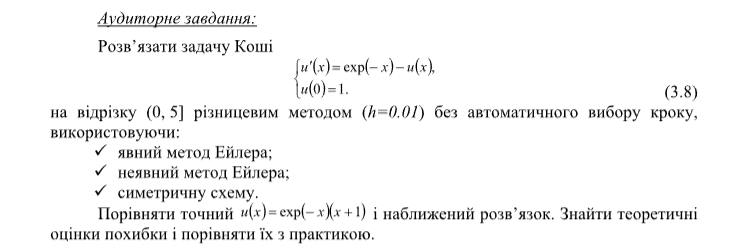

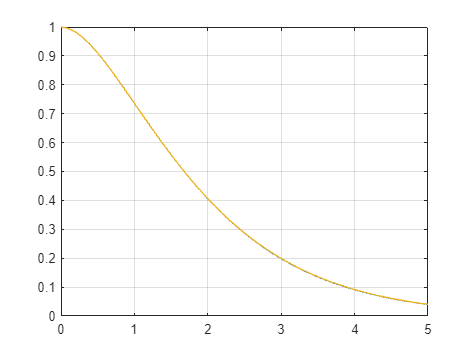

Y0 = 1;       
X = linspace(0, 5, 51); 

[T1, Y1] = ode23(@f31a, X, Y0); % розв'язання системи 
[T2, Y2] = ode45(@f31a, X, Y0); 

u = @(x)(exp(-x).*(1+x)); 
plot(T1, Y1, T2, Y2, X, u(X)), grid on;

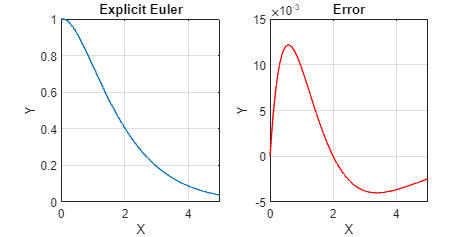


[X, Y] = eulerSolver(@f31a, 0, Y0, 5, 51, 0);
complexPlotWithError(X, Y, u, "Explicit Euler");

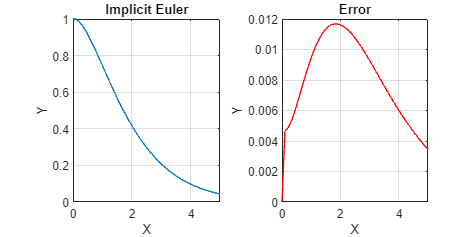


[X, Y] = eulerSolver(@f31a, 0, Y0, 5, 51, 1);
complexPlotWithError(X, Y, u, "Implicit Euler");

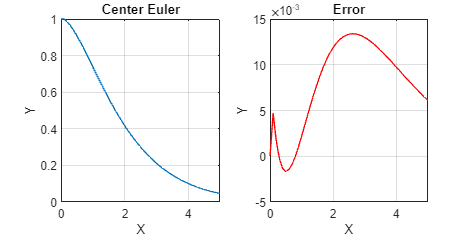


[X, Y] = eulerSolver(@f31a, 0, Y0, 5, 51, 2);
complexPlotWithError(X, Y, u, "Center Euler");

## Taks 2

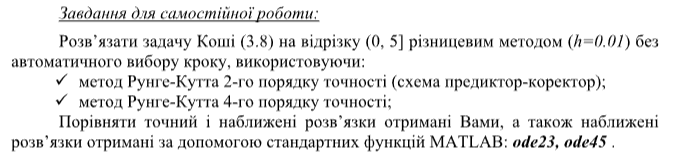

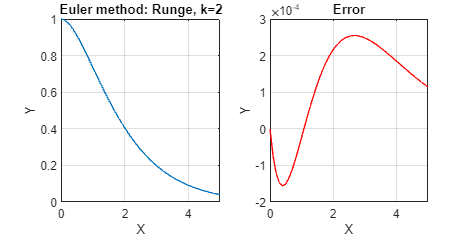

[X, Y] = runge2EulerSolver(@f31a, 0, Y0, 5, 51);
complexPlotWithError(X, Y, u, "Euler method: Runge, k=2");

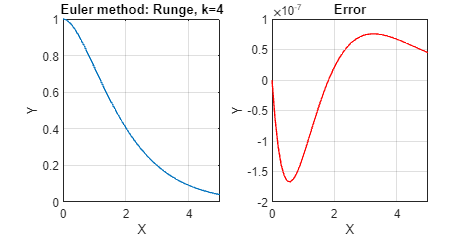


[X, Y] = runge4EulerSolver(@f31a, 0, Y0, 5, 51);
complexPlotWithError(X, Y, u, "Euler method: Runge, k=4");



export("Computational methods/Lab3.mlx")

ans = 'E:\Work\Applied math\Matlab\Lab3.pdf'

function complexPlotWithError(X, Y, explicitFunc, xLabel, yLabel, plotTitle)
    % xMin = min(X); xMax = max(X);
    % yMin = min(Y); yMax = max(Y);

    if nargin == 3
        xLabel = "X";
        yLabel = "Y";
        plotTitle = "xOy plot";
    end

    % stupid, but I don't want to creat second method
    % no default arg - welcome to matlab :/
    if nargin == 4
        plotTitle = xLabel;
        xLabel = "X";
        yLabel = "Y";
    end

    if nargin == 5
        plotTitle = "xOy plot";
    end

    fig = figure;
    fig.Position(3:4) = [800, 400];
    subplot(1, 2, 1);
    
    Y0 = explicitFunc(X);
    error = Y - Y0;

    subplot(1, 2, 1);


    plot(X, Y);
    xlim([min(X), max(X)]);

    xlabel(xLabel);
    ylabel(yLabel);
    title(plotTitle);
    
    grid on;

    subplot(1, 2, 2);
    plot(X, error, 'r');
    xlim([min(X), max(X)]);

    xlabel(xLabel);
    ylabel(yLabel);
    title("Error");
    
    grid on;
end

function F = f31a(t, U)   
    % підфункція правої частини системи 
    F = exp(-t) - U;
end

function [X, Y] = eulerSolver(dfunc, x0, u0, xn, n, side)
    if x0 >= xn
        error("eulerSolver: x0 >= xn");
    end


    if side == 0
        [X, Y] = eulerSolverLeft(dfunc, x0, u0, xn, n);
        return
    end

    if side == 1
        [X, Y] = eulerSolverCenter(dfunc, x0, u0, xn, n);
        return
    end
    
    [X, Y] = eulerSolverRight(dfunc, x0, u0, xn, n);
end

function [X, Y] = eulerSolverLeft(dfunc, x0, u0, xn, n)
    dx = (xn - x0) / n;
    X = x0:dx:xn;
    Y = u0;

    y0 = u0;
    for i=2:length(X)
        y1 = y0 + dx * dfunc(x0, y0);
        x0 = x0 + dx;
        y0 = y1;
        Y(i) = y0;
    end
end

function [X, Y] = eulerSolverCenter(dfunc, x0, u0, xn, n)
    dx = (xn - x0) / n;
    X = linspace(x0, xn, n);
    Y = u0;

    y0 = u0;
    for i=2:length(X)

        if i == 2
            y1 = y0;
        else
            F = @(y)(y - dx*(dfunc(x0, y0) + dfunc(x0 + dx, y))/2 - y0);
            y1 = newton(F, y0);
        end

        y0 = y1;
        x0 = x0 + dx;
        Y(i) = y0;
    end
end

function [X, Y] = eulerSolverRight(dfunc, x0, u0, xn, n)
    dx = (xn - x0) / n;
    X = linspace(x0, xn, n);
    Y = u0;

    y0 = u0;
    for i=2:length(X)
        x0 = x0 + dx;

        if i == 2
            y1 = y0;
        else
            F = @(y)(y - dx*dfunc(x0, y) - y0);
            y1 = newton(F, y0);
        end

        y0 = y1;
        Y(i) = y0;
    end
end

function y0 = newton(f, y0)
    eps = 10^(-9);

    depth = 300; k = 0;
    while f(y0) ~= 0 && k < depth 
        df = (f(y0 + eps) - f(y0)) / eps;

        y0 = y0 - f(y0) / df;
        k = k + 1;
    end
end

function [X, Y] = runge2EulerSolver(dfunc, x0, u0, xn, n)
    dx = (xn - x0) / n;
    X = x0:dx:xn;
    Y = u0;

    gamma = 0.5;
    A1 = gamma; A2 = 1 - gamma;

    y0 = u0;
    for i=2:length(X)
        K1 = dfunc(x0, y0);
        K2 = dfunc(x0 + dx / (2*gamma), y0 + dx / (2*gamma) * K1);

        y1 = y0 + dx * (A1 * K1 + A2 * K2);
        x0 = x0 + dx;
        y0 = y1;
        Y(i) = y0;
    end
end

function [X, Y] = runge4EulerSolver(dfunc, x0, u0, xn, n)
    dx = (xn - x0) / n;
    X = x0:dx:xn;
    Y = u0;

    [A1, A2, A3, A4] = deal(1/6, 1/3, 1/3, 1/6);

    y0 = u0;
    for i=2:length(X)
        K1 = dfunc(x0, y0);
        K2 = dfunc(x0 + dx / 2, y0 + dx / 2 * K1);
        K3 = dfunc(x0 + dx / 2, y0 + dx / 2 * K2);
        K4 = dfunc(x0 + dx, y0 + dx * K3);

        y1 = y0 + dx * (A1 * K1 + A2 * K2 + A3 * K3 + A4 * K4);
        x0 = x0 + dx;
        y0 = y1;
        Y(i) = y0;
    end
end